# Aufgabe 2: Erkennung von Sprachkommandos

Hier soll ein vollverbundenes Neuronales Netz zur Erkennung von Sprachkommandos erstellt werden. Um einen brauchbaren Klassifikator zu erhalten, ist es ungünstig, mit den Audio-Rohdaten zu arbeiten. Ein besserer Ansatz besteht darin, zuerst aus jeder Audio-Datei ein Spektrogramm zu erstellen und damit ein Neuronales Netz zu trainieren.

### Aufgabe 2 (a) Hintergrund wiederholen

Wiederholen Sie die Begriffe *Kurzzeit-FFT* und *Spektrogramm* aus Ihrer Lieblingsvorlesung zur digitalen Signalverarbeitung.

### Aufgabe 2 (b) Einlesen der Daten

Das Einlesen der Audio-Dateien kann mit einem `audioDatastore`-Objekt (Doku lesen!) erledigt werden, was den ganzen Prozess deutlich vereinfacht.

adsTrain = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'train'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
adsTest = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'test'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
% Klassenverteilung der Trainingsdaten auflisten:
tabulate(adsTrain.Labels);

  Value    Count   Percent
     go      750     25.00%
   left      750     25.00%
  right      750     25.00%
   stop      750     25.00%


Ein Beispiel für ein Spektrogramm ansehen:

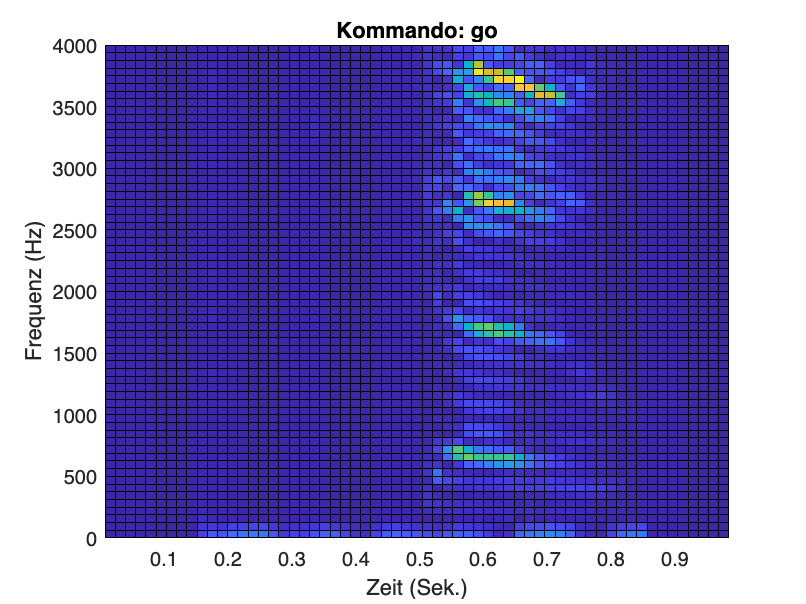

[~, fs] = audioread(adsTrain.Files{1});
win = hamming(128); 
[y, i] = adsTrain.read(); 
[specMat, f,t] = spectrogram(y, win, 0, length(win), fs); 
figure; 
pcolor(t, f, abs(specMat));
title(sprintf('Kommando: %s', i.Label)); 
xlabel('Zeit (Sek.)'), ylabel('Frequenz (Hz)');

Parameter festlegen: 

C = length(categories(adsTrain.Labels));    % Anzahl Klassen
nTrain = length(adsTrain.Labels);
nTest = length(adsTest.Labels);
P = numel(specMat);      % Anzahl Merkmale

Trainingsdaten einlesen:


count = 0; 
trainMat = zeros(nTrain,P);
adsTrain.reset();     % Lesepointer auf Anfang setzen
tic
while adsTrain.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTrain.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   % TODO: ab hier weiter machen!
   A = reshape(sm, 1, []);
   trainMat(count, :) = A;
end

toc

Elapsed time is 34.779506 seconds.


assert(count == nTrain);   % Wurden wirklich alle Daten gelesen? 

Testdaten einlesen:

count = 0; 
testMat = zeros(nTest,P);
adsTest.reset();     % Lesepointer auf Anfang setzen
tic
while adsTest.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTest.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   A = reshape(sm, 1, []);
   testMat(count, :) = A;
end

toc

Elapsed time is 37.740516 seconds.


assert(count == nTrain);

### Aufgabe 2 (c) Softmax-Modell trainieren

Trainieren Sie zuerst ein Softmax-Modell. Welchen Trainings- und Testfehler erreichen Sie? Stellen Sie auch die Confusion-Matrix graphisch dar (siehe Beispiel-Code zu Kapitel 7).

%Normieren
m = mean(trainMat);
s = std(trainMat);
normTrainMat = (trainMat-m)./s;

lambda = 0;

options = trainingOptions('rmsprop',...
   'ValidationData', {abs(trainMat), adsTrain.Labels}, ...
   'MaxEpochs', 150, ...
   'MinibatchSize', 300, ...
   'L2Regularization', lambda, ...
   'Verbose', true, ...
   'Plots', 'none', ...
   'LearnRateDropFactor', 0.02, ...
   'LearnRateDropPeriod', 15);% training-progress'); 

layers = [featureInputLayer(P)
    batchNormalizationLayer
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];
tic
net = trainNetwork(abs(trainMat), categorical(adsTrain.Labels), layers, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       18.00% |       34.17% |       2.0073 |       1.9017 |          0.0010 |
|       5 |          50 |       00:00:01 |       75.00% |       67.63% |       0.7300 |       0.7832 |          0.0010 |
|      10 |         100 |       00:00:02 |       79.67% |       73.20% |       0.5719 |       0.6509 |          0.0010 |
|      15 |         150 |       00:00:03 |       85.33% |       76.73% |       0.4669 |       0.5961 |          0.0010 |
|      2

toc

Elapsed time is 21.734391 seconds.


tic
[yneu, pMat] = classify(net, abs(testMat));
toc

Elapsed time is 1.459833 seconds.


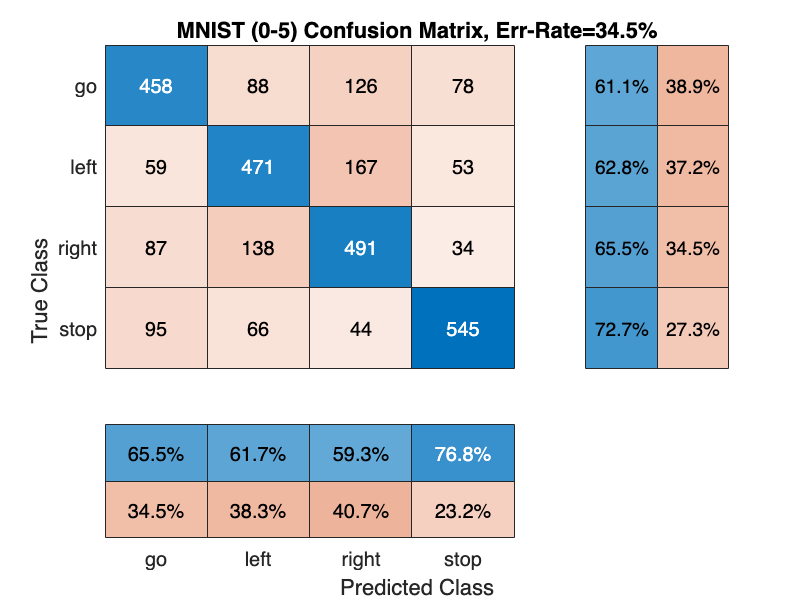


errTest = sum(yneu ~= adsTest.Labels) / length(adsTest.Labels);

cmTest = confusionmat(adsTest.Labels, yneu);

cc = confusionchart(cmTest, categories(adsTest.Labels));
cc.ColumnSummary = 'column-normalized'; 
cc.RowSummary = 'row-normalized';
cc.Title = sprintf('MNIST (0-5) Confusion Matrix, Err-Rate=%.1f%%', 100*errTest);

### Aufgabe 2 (d) Vollverbundes Netz entwerfen

Erstellen Sie ein Neuronales Netz mit mindestens 3 vollverbundenen Schichten. Welchen Trainings- und Testfehler können Sie jetzt erreichen? Stellen Sie ebenfalls die Confusion-Matrix graphisch dar. Versuchen Sie auf einen Testfehler unter 20% zu kommen. 

(P.S.: Versuchen Sie doch mal, die Lernratendämpfung (siehe Ende Kap. 5) beim Training zu aktivieren. Das könnte die Leistung des Netzes verbessern.)

H = 80;
lambda = 0;
options = trainingOptions('adam',...
   'ValidationData', {abs(trainMat), adsTrain.Labels}, ...
   'MaxEpochs', 150, ...
   'MinibatchSize', 300, ...
   'L2Regularization', lambda, ...
   'Verbose', true, ...
   'Plots', 'none', ...
   'LearnRateDropFactor', 0.01, ...
   'LearnRateDropPeriod', 15); % training-progress'); 

layers = [featureInputLayer(P)
    batchNormalizationLayer
   fullyConnectedLayer(H)
   reluLayer
   fullyConnectedLayer(H)
   reluLayer
   fullyConnectedLayer(C)
   softmaxLayer
   classificationLayer];
tic
net = trainNetwork(abs(trainMat), categorical(adsTrain.Labels), layers, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       22.67% |       33.53% |       1.7851 |       1.4345 |          0.0010 |
|       5 |          50 |       00:00:01 |       90.67% |       88.67% |       0.3199 |       0.3291 |          0.0010 |
|      10 |         100 |       00:00:02 |       91.00% |       90.77% |       0.2468 |       0.2504 |          0.0010 |
|      15 |         150 |       00:00:04 |       90.67% |       86.87% |       0.2791 |       0.3414 |          0.0010 |
|      2

toc

Elapsed time is 38.198239 seconds.



tic
[yneu, pMat] = classify(net, abs(testMat));
toc

Elapsed time is 0.630405 seconds.


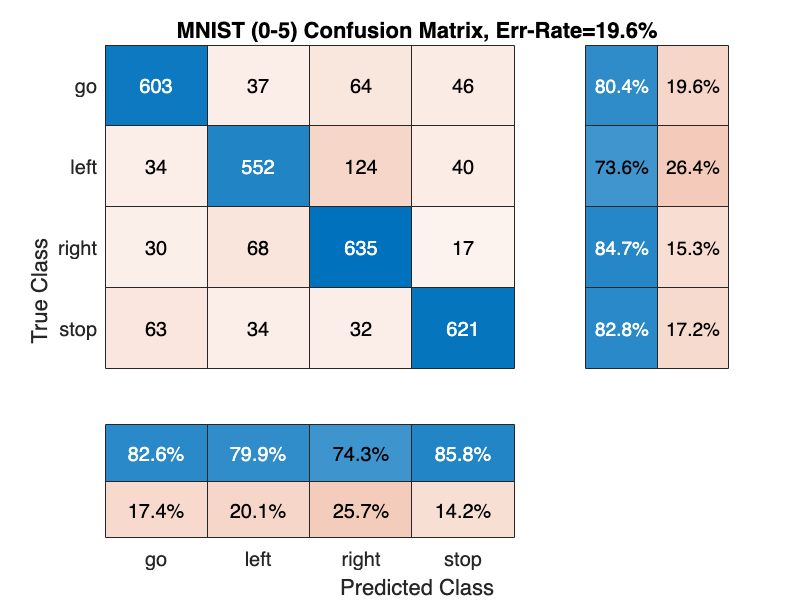


errTest = sum(yneu ~= adsTest.Labels) / length(adsTest.Labels);

cmTest = confusionmat(adsTest.Labels, yneu);

cc = confusionchart(cmTest, categories(adsTest.Labels));
cc.ColumnSummary = 'column-normalized'; 
cc.RowSummary = 'row-normalized';
cc.Title = sprintf('MNIST (0-5) Confusion Matrix, Err-Rate=%.1f%%', 100*errTest);